## read in data

format compact
data =readmatrix('MM_data.xlsx');
%set up xobs, yobs into vectors
%x-S, y-V
xobs = data(:,1)

xobs =      0
   100
   200
   300
   400
   500
   600
   700
   800
   900


yobs = data(:,2)

yobs =    0.014699480743730
   0.048826281221700
   0.106724093324253
   0.141992035575095
   0.204523471312132
   0.209353199919052
   0.241370109354611
   0.216147101297313
   0.243423313029537
   0.218829177530894


## parameter guesses; define beta0

fnameFOR=@MM2;

%beta0(1) = Vmax, beta0(2) = Km
beta0(1) = 0.5

beta0 = 	1.0e+02 *

   0.005000000000000   4.000000000000000


beta0(2) = 400

beta0 = 	1.0e+02 *

   0.005000000000000   4.000000000000000


p=length(beta0)

p =      2

## Scaled sensitivity coefficients before running inverse problem

%to determine a) which parameters can be estimated, and b) which parameters
%wil be most accurate (lowest relative error)
xs = min(xobs):1:max(xobs); %xs are the times for SSCs to make a smooth curve.
xs=xs';%make xs a column.
ns=length(xs);%length of xs for plotting

ypredInit = fnameFOR(beta0, xs)

ypredInit =                    0
   0.001246882793017
   0.002487562189055
   0.003722084367246
   0.004950495049505
   0.006172839506173
   0.007389162561576
   0.008599508599509
   0.009803921568627
   0.011002444987775


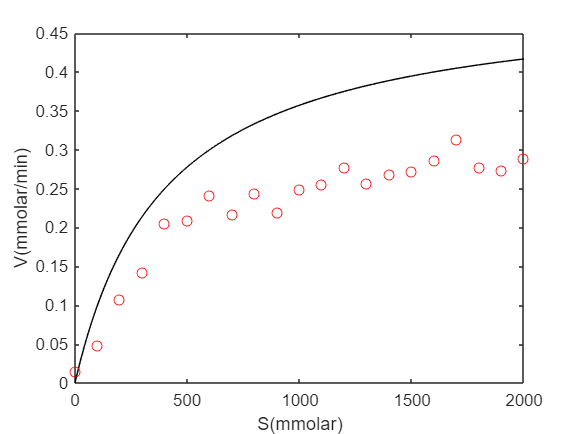

plot(xs,ypredInit,'-k',xobs,yobs,'or');
xlabel('S(mmolar)');
ylabel('V(mmolar/min)');


Xp=SSC_V3(beta0,xs,fnameFOR)

Xp =                    0                   0
   0.001246882793017  -0.001242533924282
   0.002487562189055  -0.002472725834050
   0.003722084367245  -0.003690713304160
   0.004950495049504  -0.004896632096444
   0.006172839506172  -0.006090616187639
   0.007389162561576  -0.007272797796826
   0.008599508599508  -0.008443307412379
   0.009803921568626  -0.009602273818439
   0.011002444987774  -0.010749824120932


## plot X' for each dependent variable

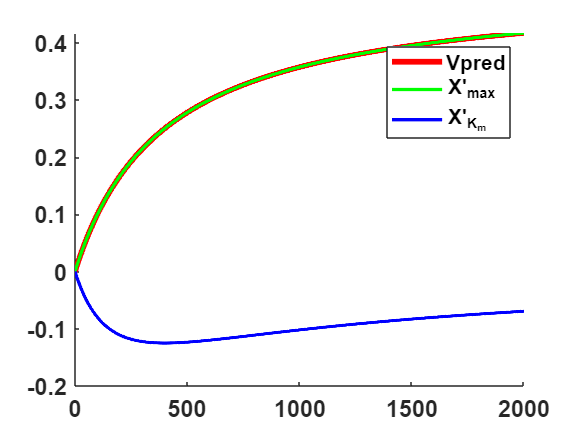

%plot for V
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]';
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
%plot V vs t to know the total span

ypred=fnameFOR(beta0,xs);
h2(1)=plot(xs(1:ns),ypred(1:ns),'-','color',cmap(1,:),'LineWidth',3.5); %plot the predicted C to compare to SSCs
for i=1:p
    h2(i+1) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend('Vpred','X''_V_{max}','X''_{K_m}')

%nlinfit returns parameters, residuals, Jacobian (sensitivity coefficient matrix), 
%covariance matrix, and mean square error
fnameINV=@MM2 %%put the name of your inverse function here

fnameINV = 包含以下值的 function_handle :
    @MM2

[beta,resids,J,COVB,mse] = nlinfit(xobs, yobs,fnameINV,beta0);
Vmax=beta(1)

Vmax =    0.346321575700589

Km=beta(2)

Km =      3.767534184497632e+02

rmse=sqrt(mse)

rmse =    0.016499087833333

rmseunits='mmolarpermin'

rmseunits = 'mmolarpermin'

condX=cond(J)

condX =      1.003062208513388e+04

detXTX=det(J'*J)

detXTX =      9.248565111468079e-07

%R is the correlation matrix for the parameters, sigma is the standard deviation vector
[R,sigma]=corrcov(COVB);
R

R =    1.000000000000000   0.921970177943583
   0.921970177943583   1.000000000000000


corr12=R(2,1) %correlation coefficient between the 2 parameters

corr12 =    0.921970177943583

sigma

sigma =    0.013717462841858
  53.285036399272464


relerr=sigma./beta'

relerr =    0.039609033350315
   0.141432124540570


relerr1=100*relerr(1) %percent error beta1

relerr1 =    3.960903335031475

relerr2=100*relerr(2) %percent error beta2

relerr2 =   14.143212454057020


ypredp=MM2(beta,xs);
yspan=range(ypredp)

yspan =    0.291424068657890

relrmse=rmse/yspan

relrmse =    0.056615391821674

## confidence intervals for parameters

%use nlparci
ci=nlparci(beta, resids,J)

ci = 	1.0e+02 *

   0.003176105960071   0.003750325553941
   2.652265555260635   4.882802813734628


CIu1 = ci(1, 2)

CIu1 =    0.375032555394051

CIL2 = ci(2, 1)

CIL2 =      2.652265555260635e+02


%nonlinear regression confidence intervals-- 'on' means simultaneous
%bounds; 'off' is for nonsimultaneous bounds; must use 'curve' for
%regression line, 'observation' for prediction interval
[ypred, delta] = nlpredci(fnameINV,xobs,beta,resids,J,0.05,'on','curve'); %confidence band for regression line
[ypred, deltaob] =nlpredci(fnameINV,xobs,beta,resids,J,0.05,'on','observation');%prediction band for individual points


## simultaneous confidence bands for regression line

CBu=ypred+delta;
CBl=ypred-delta;

%simultaneous prediction bands for regression line
PBu=ypred+deltaob;
PBl=ypred-deltaob;

V1000=fnameFOR(beta,1000) %ypred @ 1000

V1000 =    0.251549457629494

S1000=find(xobs==1000,1);
CBu1000=CBu(S1000)

CBu1000 =    0.261893406500992

PBl1000=PBl(S1000)

PBl1000 =    0.199621652661396

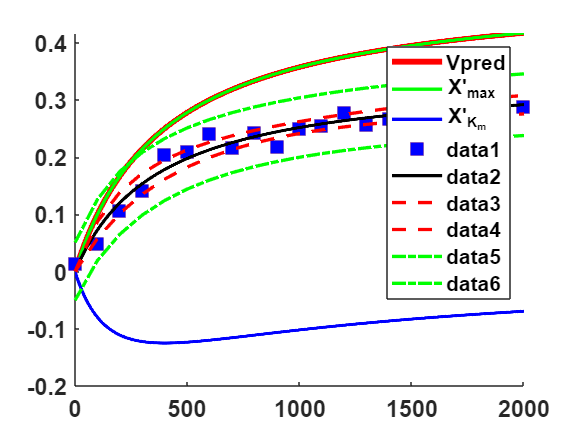


%plot yobs, ypred line, confidence band for regression line
ypredp=fnameFOR(beta,xs); %gives smooth line for ypred 

h1(1)=plot(xobs,yobs,'square', 'Markerfacecolor', 'b','markersize',10); %observed
h1(2) = plot(xs,ypredp,'-k','LineWidth',2); %predicted
h1(3) = plot(xobs,CBu,'--r','LineWidth',2); %upper CB
plot(xobs,CBl,'--r','LineWidth',2); %lower CB doesn't need a legend

%plot prediction band for regression line
h1(4) = plot(xobs,PBu,'-.g','LineWidth',2); %upper PB
plot(xobs,PBl,'-.g','LineWidth',2);  %lower PB doesn't need a legend


meanres=mean(resids);
resid10=   resids(10)        

resid10 =   -0.025297380993605

meanres

meanres =      2.183489171170283e-05

## Scaled sensitivity coefficients before running inverse problem

%to determine a) which parameters can be estimated, and b) which parameters
%wil be most accurate (lowest relative error)

Xp=SSC_V3(beta,xs,fnameFOR);

## plot X' for each dependent variable

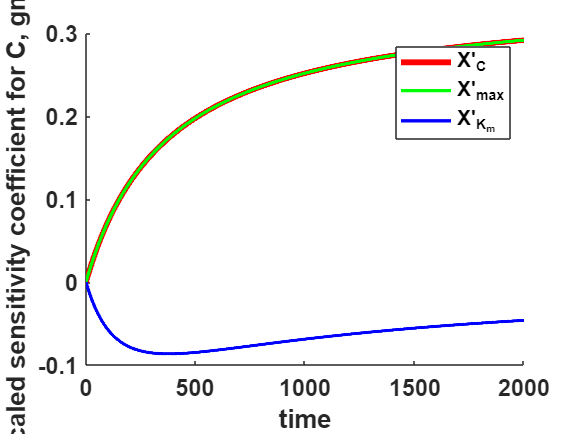

%plot for C
cmap = ['r' 'g' 'b' 'c' 'y'  'm' 'k' ]';
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
%plot C vs t to know the total span
ypred=fnameFOR(beta,xs);
h2(1)=plot(xs(1:ns),ypred(1:ns),'-','color',cmap(1,:),'LineWidth',3.5); %plot the predicted C to compare to SSCs
for i=1:p
    h2(i+1) = plot(xs(1:ns),Xp(1:ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend('X''_C','X''_V_{max}','X''_{K_m}')
xlabel('time'); ylabel('scaled sensitivity coefficient for C, gmol/L');


xs

xs =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


xobs

xobs =      0
   100
   200
   300
   400
   500
   600
   700
   800
   900


Xp

Xp =                    0                   0
   0.000916792698056  -0.000913454700787
   0.001828744290246  -0.001817279958030
   0.002735893020642  -0.002711589671964
   0.003638276731545  -0.003596496150270
   0.004535932868747  -0.004472110134105
   0.005428898486705  -0.005338540823630
   0.006317210253648  -0.006195895903081
   0.007200904456593  -0.007044281565350
   0.008080017006281  -0.007883802536123


S1000=find(xs==1000)

S1000 =         1001

SSC1_1000=Xp(S1000,1)

SSC1_1000 =    0.251549457629452

SSC2_1000=Xp(S1000,2)

SSC2_1000 =   -0.068818561968331

## residual scatter plot

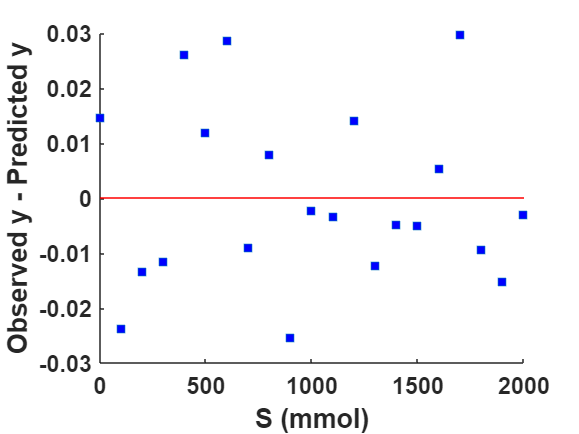

figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
plot(xobs, resids, 'square', 'Markerfacecolor', 'b')
plot([0,max(xobs)],[0,0], 'R')
ylabel('Observed y - Predicted y','fontsize',16,'fontweight','bold')
xlabel('S (mmol)','fontsize',16,'fontweight','bold')

## residuals histogram--same as dfittool, but no curve fit here

 figure
h=histogram(resids)

h =   Histogram - 属性:

             Data: [21×1 double]
           Values: [2 11 5 3]
          NumBins: 4
         BinEdges: [-0.040000000000000 -0.020000000000000 0 0.020000000000000 0.040000000000000]
         BinWidth: 0.020000000000000
        BinLimits: [-0.040000000000000 0.040000000000000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性

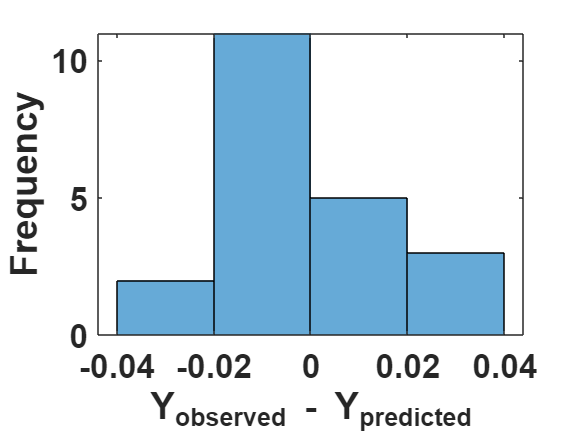

 xlabel('Y_{observed} - Y_{predicted}','fontsize',16,'fontweight','bold')
 ylabel('Frequency','fontsize',16,'fontweight','bold')
set(gca, 'fontsize',20,'fontweight','bold');

## standard statistical assumptions

function Vpred = MM2(beta,S)
    %Michaelis-Menten model
    Vpred= ( beta(1) * S ) ./ ( beta(2) + S );
end

function Xp=SSC_V3(beta,x,yfunc)
%Computes scaled sensitivity coefficients =Xp, nxp matrix
%can have k dependent variables that are stacked in a column vector
%all y1s, then all y2s, ...last are yks
%n is the number of data
%p is the number of parameters
%Xp1 = dY/dbeta1~[y(beta1(1+d), beta2,...betap) - y(beta1,
%beta2,...betap)]/d...
%d is the arbitrary delta, usually 0.001
%beta is the p x 1 parameter vector
%yhat is nx1 vector, the y values when only one parameter has been successively perturbed by d
%ypred is nx1 vector,  the y values when parameters are set to beta
%betain is px1 vector, the parameter values with only one parameter perturbed by d
%x are the independent variables (can be one or more independent variables)
%yfunc is a function (m file or an anonymous) defined by the user outside
%of this file
d=0.001;
ypred=yfunc(beta,x);
for i = 1:length(beta)  %scaled sens coeff for forward problem
    betain = beta; %reset beta
    betain(i) = beta(i)*(1+d);
    yhat{i} = yfunc(betain,x);
    SSC{i} = (yhat{i}-ypred)/d;%scaled sens coeff for ith parameter
    Xp(:,i)=SSC{i}; %extract from cell array to 2D array
end
end